# Machine Learning Online Class - Exercise 4 Neural Network Learning

%  Instructions
%  ------------
% 
%  This file contains code that helps you get started on the
%  linear exercise. You will need to complete the following functions 
%  in this exericse:
%
%     sigmoidGradient.m
%     randInitializeWeights.m
%     nnCostFunction.m
%
%  For this exercise, you will not need to change any code in this file,
%  or any other files other than those mentioned above.
%

## Initialization

clear ; close all; clc

## Setup the parameters you will use for this exercise

input_layer_size  = 400;  % 20x20 Input Images of Digits
hidden_layer_size = 25;   % 25 hidden units
num_labels = 10;          % 10 labels, from 1 to 10   
                          % (note that we have mapped "0" to label 10)

## =========== Part 1: Loading and Visualizing Data =============

% Load Training Data
fprintf('Loading and Visualizing Data ...\n')

Loading and Visualizing Data ...


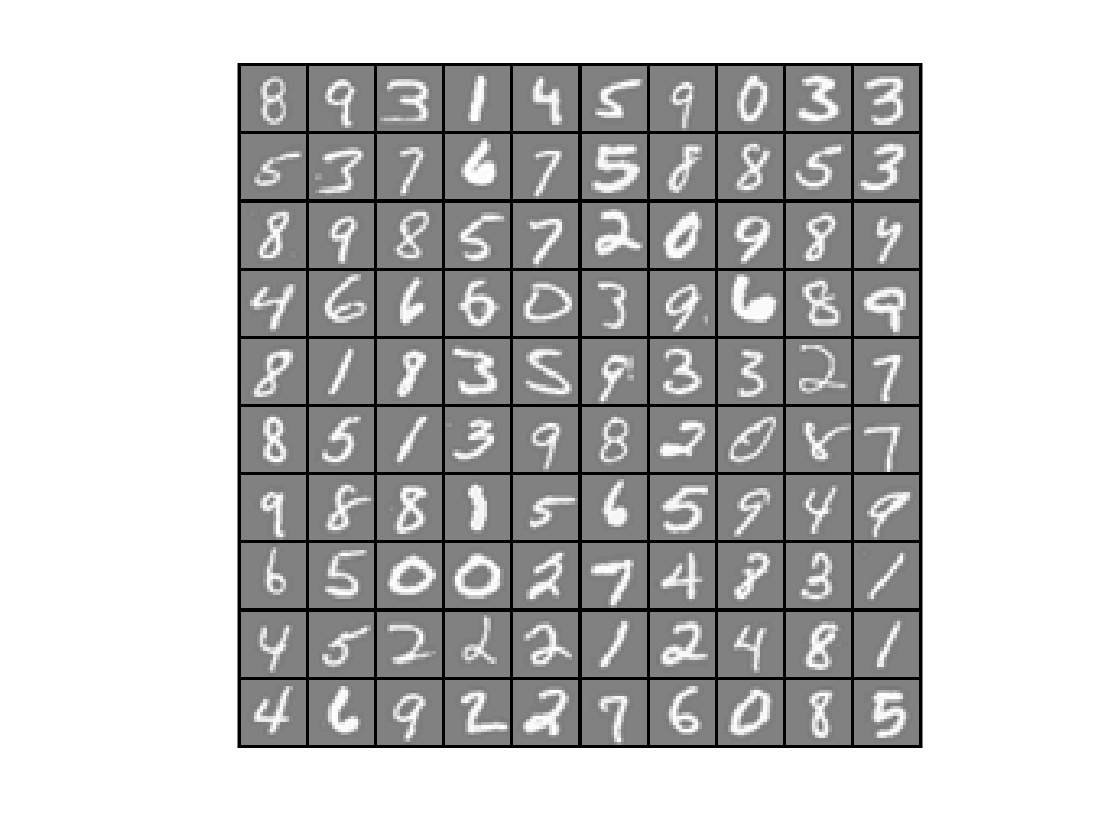


load('ex4data1.mat');
m = size(X, 1);

% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);

displayData(X(sel, :));


fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## ================ Part 2: Loading Parameters ================

In this part of the exercise, we load some pre-initialized neural network parameters.

fprintf('\nLoading Saved Neural Network Parameters ...\n')


Loading Saved Neural Network Parameters ...



% Load the weights into variables Theta1 and Theta2
load('ex4weights.mat');

% Unroll parameters 
nn_params = [Theta1(:) ; Theta2(:)];

## ================ Part 3: Compute Cost (Feedforward) ================

fprintf('\nFeedforward Using Neural Network ...\n')


Feedforward Using Neural Network ...



% Weight regularization parameter (we set this to 0 here).
lambda = 0;

J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, ...
                   num_labels, X, y, lambda);

fprintf(['Cost at parameters (loaded from ex4weights): %f '...
         '\n(this value should be about 0.287629)\n'], J);

Cost at parameters (loaded from ex4weights): 0.287629 
(this value should be about 0.287629)



fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;

## =============== Part 4: Implement Regularization ===============

fprintf('\nChecking Cost Function (w/ Regularization) ... \n')


Checking Cost Function (w/ Regularization) ... 



% Weight regularization parameter (we set this to 1 here).
lambda = 1;

J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, ...
                   num_labels, X, y, lambda);

fprintf(['Cost at parameters (loaded from ex4weights): %f '...
         '\n(this value should be about 0.383770)\n'], J);

Cost at parameters (loaded from ex4weights): 0.383770 
(this value should be about 0.383770)



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## ================ Part 5: Sigmoid Gradient ================

fprintf('\nEvaluating sigmoid gradient...\n')


Evaluating sigmoid gradient...



g = sigmoidGradient([-1 -0.5 0 0.5 1]);
fprintf('Sigmoid gradient evaluated at [-1 -0.5 0 0.5 1]:\n  ');

Sigmoid gradient evaluated at [-1 -0.5 0 0.5 1]:
  

fprintf('%f ', g);

0.196612 0.235004 0.250000 0.235004 0.196612 

fprintf('\n\n');


fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## ================ Part 6: Initializing Pameters ================

fprintf('\nInitializing Neural Network Parameters ...\n')


Initializing Neural Network Parameters ...



initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, num_labels);

% Unroll parameters
initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:)];

## =============== Part 7: Implement Backpropagation ===============

fprintf('\nChecking Backpropagation... \n');


Checking Backpropagation... 



%  Check gradients by running checkNNGradients
checkNNGradients;

   -0.0093   -0.0093
    0.0089    0.0089
   -0.0084   -0.0084
    0.0076    0.0076
   -0.0067   -0.0067
   -0.0000   -0.0000
    0.0000    0.0000
   -0.0000   -0.0000
    0.0000    0.0000
   -0.0000   -0.0000
   -0.0002   -0.0002
    0.0002    0.0002
   -0.0003   -0.0003
    0.0003    0.0003
   -0.0004   -0.0004
   -0.0001   -0.0001
    0.0001    0.0001
   -0.0001   -0.0001
    0.0002    0.0002
   -0.0002   -0.0002
    0.3145    0.3145
    0.1111    0.1111
    0.0974    0.0974
    0.1641    0.1641
    0.0576    0.0576
    0.0505    0.0505
    0.1646    0.1646
    0.0578    0.0578
    0.0508    0.0508
    0.1583    0.1583
    0.0559    0.0559
    0.0492    0.0492
    0.1511    0.1511
    0.0537    0.0537
    0.0471    0.0471
    0.1496    0.1496
    0.0532    0.0532
    0.0466    0.0466

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your backpropagation implementation is correct, then 
the relative difference will be


fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;

## =============== Part 8: Implement Regularization ===============

fprintf('\nChecking Backpropagation (w/ Regularization) ... \n')


Checking Backpropagation (w/ Regularization) ... 



%  Check gradients by running checkNNGradients
lambda = 3;
checkNNGradients(lambda);

   -0.0093   -0.0093
    0.0089    0.0089
   -0.0084   -0.0084
    0.0076    0.0076
   -0.0067   -0.0067
   -0.0168   -0.0168
    0.0394    0.0394
    0.0593    0.0593
    0.0248    0.0248
   -0.0327   -0.0327
   -0.0602   -0.0602
   -0.0320   -0.0320
    0.0249    0.0249
    0.0598    0.0598
    0.0386    0.0386
   -0.0174   -0.0174
   -0.0576   -0.0576
   -0.0452   -0.0452
    0.0091    0.0091
    0.0546    0.0546
    0.3145    0.3145
    0.1111    0.1111
    0.0974    0.0974
    0.1187    0.1187
    0.0000    0.0000
    0.0337    0.0337
    0.2040    0.2040
    0.1171    0.1171
    0.0755    0.0755
    0.1257    0.1257
   -0.0041   -0.0041
    0.0170    0.0170
    0.1763    0.1763
    0.1131    0.1131
    0.0862    0.0862
    0.1323    0.1323
   -0.0045   -0.0045
    0.0015    0.0015

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your backpropagation implementation is correct, then 
the relative difference will be


% Also output the costFunction debugging values
debug_J  = nnCostFunction(nn_params, input_layer_size, ...
                          hidden_layer_size, num_labels, X, y, lambda);

fprintf(['\n\nCost at (fixed) debugging parameters (w/ lambda = %f): %f ' ...
         '\n(for lambda = 3, this value should be about 0.576051)\n\n'], lambda, debug_J);



Cost at (fixed) debugging parameters (w/ lambda = 3.000000): 0.576051 
(for lambda = 3, this value should be about 0.576051)




fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =================== Part 8: Training NN ===================

fprintf('\nTraining Neural Network... \n')


Training Neural Network... 



%  After you have completed the assignment, change the MaxIter to a larger
%  value to see how more training helps.
options = optimset('MaxIter', 50);

%  You should also try different values of lambda
lambda = 1;

% Create "short hand" for the cost function to be minimized
costFunction = @(p) nnCostFunction(p, ...
                                   input_layer_size, ...
                                   hidden_layer_size, ...
                                   num_labels, X, y, lambda);

% Now, costFunction is a function that takes in only one argument (the
% neural network parameters)
[nn_params, cost] = fmincg(costFunction, initial_nn_params, options);

Iteration     1 | Cost: 3.312223e+00
Iteration     2 | Cost: 3.248407e+00
Iteration     3 | Cost: 3.224486e+00
Iteration     4 | Cost: 2.732686e+00
Iteration     5 | Cost: 2.420609e+00
Iteration     6 | Cost: 2.181786e+00
Iteration     7 | Cost: 1.882061e+00
Iteration     8 | Cost: 1.717942e+00
Iteration     9 | Cost: 1.594550e+00
Iteration    10 | Cost: 1.499943e+00
Iteration    11 | Cost: 1.390117e+00
Iteration    12 | Cost: 1.303157e+00
Iteration    13 | Cost: 1.216663e+00
Iteration    14 | Cost: 1.121602e+00
Iteration    15 | Cost: 1.076398e+00
Iteration    16 | Cost: 1.060762e+00
Iteration    17 | Cost: 1.003654e+00
Iteration    18 | Cost: 9.732858e-01
Iteration    19 | Cost: 9.432212e-01
Iteration    20 | Cost: 9.094492e-01
Iteration    21 | Cost: 8.750190e-01
Iteration    22 | Cost: 8.360738e-01
Iteration    23 | Cost: 7.951512e-01
Iteration    24 | Cost: 7.750537e-01
Iteration    25 | Cost: 7.562736e-01
Iteration    26 | Cost: 7.323080e-01
Iteration    27 | Cost: 7.140256e-01
I


% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), ...
                 hidden_layer_size, (input_layer_size + 1));

Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), ...
                 num_labels, (hidden_layer_size + 1));

fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## ================= Part 9: Visualize Weights =================

fprintf('\nVisualizing Neural Network... \n')


Visualizing Neural Network... 


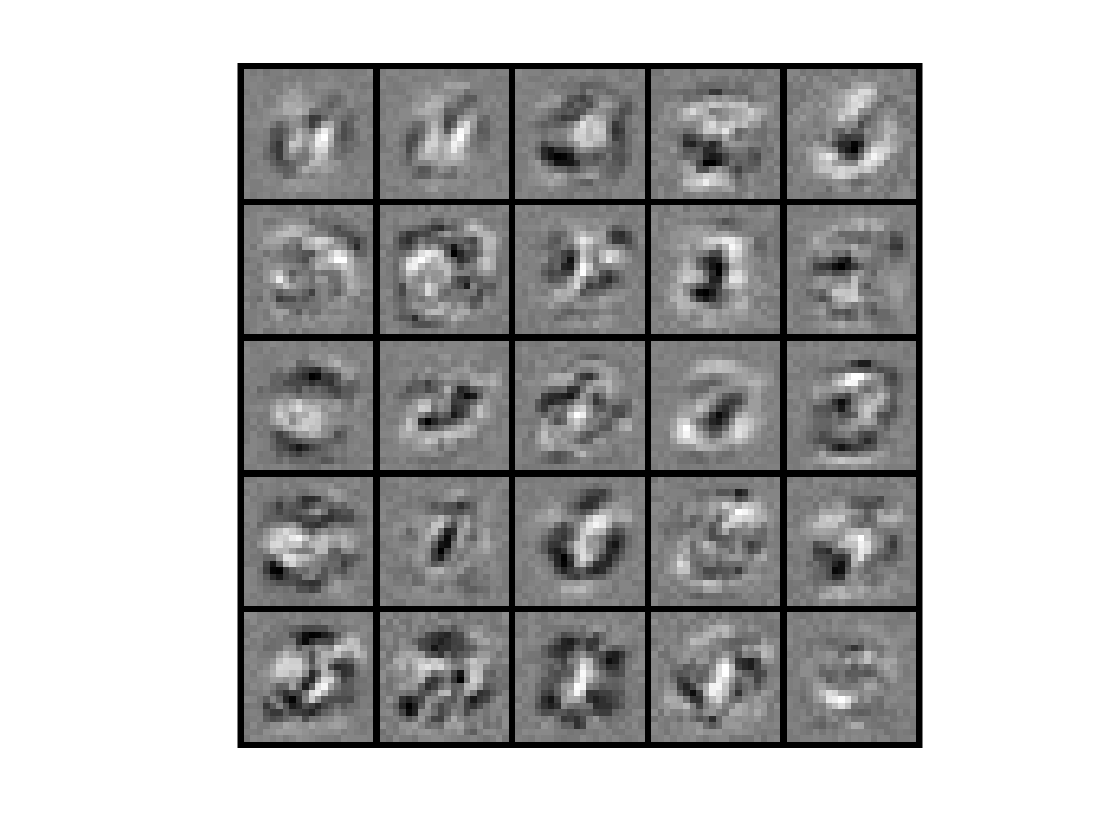


displayData(Theta1(:, 2:end));


fprintf('\nProgram paused. Press enter to continue.\n');


Program paused. Press enter to continue.


pause;

## ================= Part 10: Implement Predict =================

pred = predict(Theta1, Theta2, X);

fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);


Training Set Accuracy: 95.060000
